clear
clc

arduinoPort = '/dev/tty.usbmodem142301'

COMPORT = '/dev/tty.usbmodem142301'


robotArduino = arduino(COMPORT, 'Mega2560', 'Libraries', 'Servo') ;

panServo=servo(robotArduino,'D33','MinPulseDuration', 10*10^-6, ...
'MaxPulseDuration', 1925*10^-6) ;

writePosition(panServo,1)

figure()
data = [0 -55; 0.1 -45; 0.2 -18; 0.3 -5; 0.33 0; 0.4 5; 0.5 20;1 80];
command = data(:,1);
actual_angle = deg2rad(data(:,2));
servo_fit = fit(command,actual_angle ,'poly1')

servo_fit =      Linear model Poly1:
     servo_fit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.355  (2.048, 2.663)
       p2 =     -0.8725  (-1.012, -0.7325)

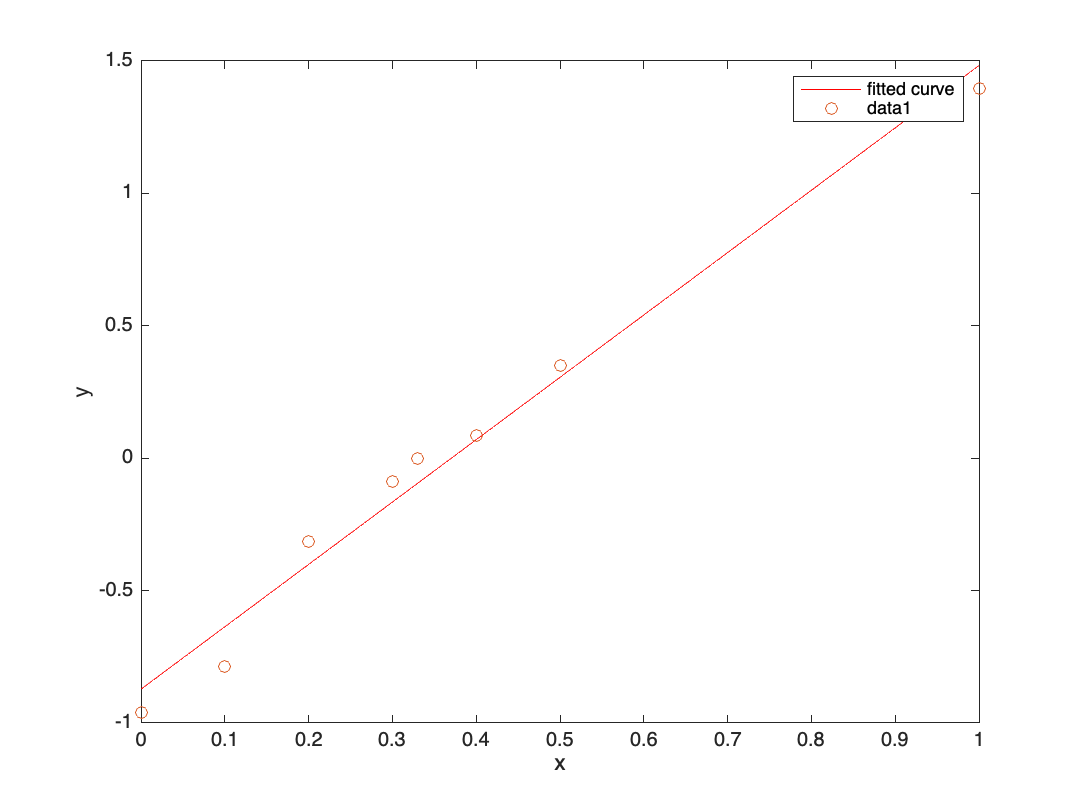

plot(servo_fit)
hold on 
plot(command, actual_angle,'o')
hold off